clear
clc
rng(1)

# Real Speed Estimation: Kalman Filter

### Ian Lum

#### 4/19/2023

## Define Time Parameters

`dt: `time step, set to 0.1 seconds

`T`: time vector, from 0 to 8 seconds with a step of 0.1 seconds

dt = 0.1;
T = 0:dt:8;

## Define Simulation Movement

The car will accellerate for 2 seconds, decelerate for 4 seconds, then accelerate for 2 seconds, coming to a stop.


$$a(t) \begin{cases} 0 \leq t \leq 2: & 5t \\ 2 < t \leq 6: & -5t+20 \\ 6 < t \leq 8: & 5t-40 \end{cases}$$



$$v(t)  = \int a(t) dt$$



$$p(t) = \int v(t) dt$$


The vectors `acceleration, velocity, `and `position`, represent the respective state of the car from time 0 to 8 seconds, with the timestep of 0.1 second.

syms a(t) v(t)
assume(0<=t & t<=8)

a(t) = piecewise( ...
    (0<=t) & (t<=2), 5*t, ...
    (2<t) & (t<=6), -5*t+20, ...
    (6<t) & (t<=8), 5*t-40);

v(t) = int(a(t),t,0,t);
p(t) = int(v(t),t,0,t);

acceleration = double(a(T));
velocity = double(v(T));
position = double(p(T));

## Plot Simulated Movement

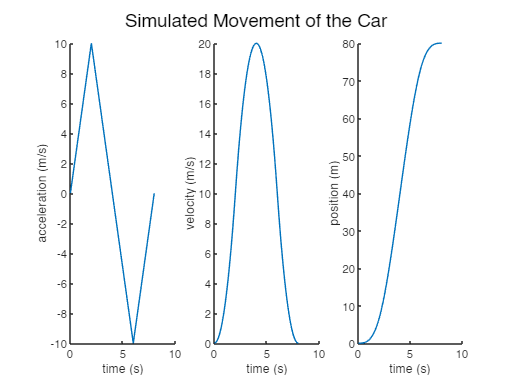

figure()
sgtitle("Simulated Movement of the Car")

subplot(1,3,1)
hold on
plot(T, acceleration)
hold off
xlabel("time (s)")
ylabel("acceleration (m/s)")

subplot(1,3,2)
hold on
plot(T, velocity)
hold off
xlabel("time (s)")
ylabel("velocity (m/s)")

subplot(1,3,3)
hold on
plot(T, position)
hold off
xlabel("time (s)")
ylabel("position (m)")

## Add Artificial Noise

In order to simulate sensor readings, noise is added onto the three states. The noise is normally distributed, and scaled by `acc_sigma, vel_sigma, `and `pos_sigma`. The `sigma` values were chosen based on very rough estimates of the error of the three sensors: IMU accelerometer, wheel speed sensor, and GPS repsectively.

`noisy_acceleration, noisy_velocity, `and `noisy_position, `represent the theoretical measurements of an IMU accelerometer, wheel speed sensor, and GPS repsectively.

acc_sigma = 1;
noisy_acceleration = acceleration + acc_sigma*randn(size(acceleration));

vel_sigma = 2;
noisy_velocity = velocity + vel_sigma*randn(size(velocity));

pos_sigma = 5;
noisy_position = position + pos_sigma*randn(size(position));

## Plot Simulated Sensor Measurements

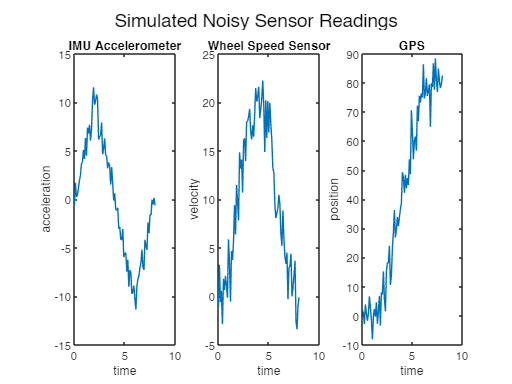

figure()
sgtitle("Simulated Noisy Sensor Readings")

subplot(1,3,1)
plot(T, noisy_acceleration)
xlabel("time")
ylabel("acceleration")
title("IMU Accelerometer")

subplot(1,3,2)
plot(T, noisy_velocity)
xlabel("time")
ylabel("velocity")
title("Wheel Speed Sensor")

subplot(1,3,3)
plot(T, noisy_position)
xlabel("time")
ylabel("position")
title("GPS")

## Running Kalman Filter

In order to run the Kalman Filter, two more variables need to be defined, `R`, representing the measurement noise covariance, and `Q`, representing the process noise covarience.

`R` is a 3x3 matrix representing the measurement noise covariance. Here `R` is defined as the square of the acceleration, velocity and position noise sigmas. These sigmas were used to scale the noise of each measurement repectively.

`Q` is a 3x3 matrix representing the initial process noise covariance. These values are all manually tuned. Here Q is defined as the identity matrix. Currently, we (Ian & Richard) are unsure how exactly `Q` impacts the Kalman filter, though we beleive it is a metric of how much to "trust" each measurement.

R = [acc_sigma^2 0 0;
    0 vel_sigma^2 0;
    0 0 pos_sigma^2];
Q = eye(3);

Now that we have those matrices defined, we can run our Kalman Filter on the noisy sensor readings.

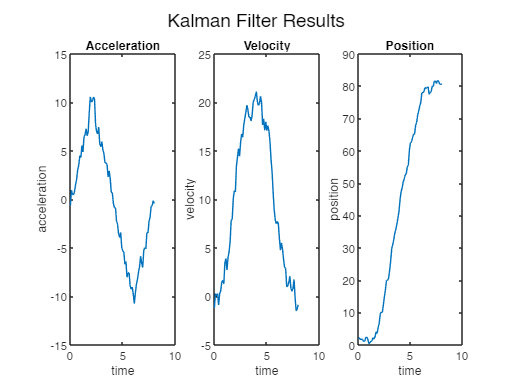

sensor_reading = [noisy_acceleration; noisy_velocity; noisy_position]';
kalman_state = run_kalman(sensor_reading, T, dt, R, Q);

figure()
sgtitle("Kalman Filter Results")

subplot(1,3,1)
plot(T, kalman_state(:,1))
xlabel("time")
ylabel("acceleration")
title("Acceleration")

subplot(1,3,2)
plot(T, kalman_state(:,2))
xlabel("time")
ylabel("velocity")
title("Velocity")

subplot(1,3,3)
plot(T, kalman_state(:,3))
xlabel("time")
ylabel("position")
title("Position")

## Parameter Sweep of `Q`

Now, we'll tune `Q` to try and optimize the Kalman Filter. While we could tweak the individual values, we'll keep `Q` as the identity matrix, scaled by a the value `q_coeff`. We'll sweep through values 0 through 10 with a 0.1 increment. How well each iteration of the Kalman filter does with a new `Q` will be defined as the sum of the mean squared error of each measurement (acceleration, velocity, position).

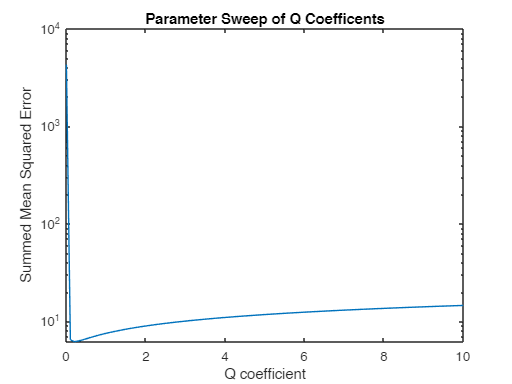

q_coeffs = 0:0.1:10;
mse = zeros(length(q_coeffs), 1);

for j=1:length(q_coeffs)

    R = [acc_sigma^2 0 0;
        0 vel_sigma^2 0;
        0 0 pos_sigma^2];
    Q = q_coeffs(j)*eye(3);
    
    state = [noisy_acceleration(1); noisy_velocity(1); noisy_position(1)];
    p_cov = Q;
    
    kalman_state = zeros(length(T), 3);
    kalman_state(1,:) = state';
    
    for i=2:length(T)
        measurement = [noisy_acceleration(i); noisy_velocity(i); noisy_position(i)];
        [state, p_cov] = kalman_update(state, p_cov, measurement, dt, R, Q);
        kalman_state(i,:) = state';
    end

    mse(j) = sum(mean((kalman_state - [acceleration' velocity' position']).^2));
end

figure()
semilogy(q_coeffs,mse)
title('Parameter Sweep of Q Coefficents')
xlabel('Q coefficient')
ylabel('Summed Mean Squared Error')

We can see that the error rapidly decreases as Q coefficient increases from 0, reaches a minimum between 0 and 1, the steadily increases.

[M, idx] = min(mse);
best_q_coeff = q_coeffs(idx)

best_q_coeff = 0.2000

## Rerunning the Kalman Filter with Best Q

We'll now run the Kalman Filter again using the best Q coefficient. We can see from the increased smoothness graph on the right that the results are marginally better than the original run.

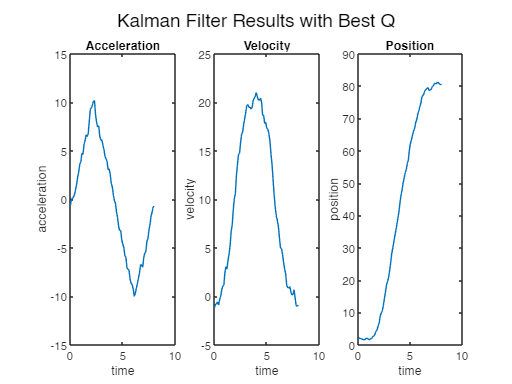

R = [acc_sigma^2 0 0;
    0 vel_sigma^2 0;
    0 0 pos_sigma^2];
Q = best_q_coeff*eye(3);

sensor_reading = [noisy_acceleration; noisy_velocity; noisy_position]';
kalman_state = run_kalman(sensor_reading, T, dt, R, Q);

figure()
sgtitle("Kalman Filter Results with Best Q")

subplot(1,3,1)
plot(T, kalman_state(:,1))
xlabel("time")
ylabel("acceleration")
title("Acceleration")

subplot(1,3,2)
plot(T, kalman_state(:,2))
xlabel("time")
ylabel("velocity")
title("Velocity")

subplot(1,3,3)
plot(T, kalman_state(:,3))
xlabel("time")
ylabel("position")
title("Position")